# **SAMOSTATNY PROJEKT BPC-SAS**

**Autor: Matyas Peroutik**

**VUT ID: 256371**

### **Úkol 1: **Analýza a číslicová filtrace signálu

V eLearningu máte dostupný audio soubor typu wav, pojmenovaný podle vašeho ID. Nahrávka obsahuje tři hlavní složky: užitečný signál (zvuk ptáčků), šum (zvuky větru a listí) a periodické rušení. K dispozici máte konečný úsek signálu. Předpokládejte, že se tento úsek neustále periodicky opakuje.

- Pomocí vhodné transformace zjistěte, jaké periodické rušení signál obsahuje. Do jednoho okna vykreslete dva grafy:

                        •  načtenou časovou řadu (tj., vzor signálu);

                        • transformovaný signál (tj., obraz signálu) — použijte logaritmické osy, vertikální i horizontální.

          2. Rušení odstraňte tím, že na obraz signálu aplikujete vhodné signálové manipulace. (Šum lesa odstraňovat nemusíte.) Pak obraz signálu převeďte zpět do časové oblasti. Upravený obraz i signál dokreslete do grafů z bodu 1.

#### Zpracovani:

Pred zacatkem zpracovani prvni ulohy vycistime pameti matlabu

clear;
clc;
close all;

Jako prvni si do matlabu nactu soubor s audiosouborem, ktery mam upravit. Nasta

filepath = "/home/neo/Documents/Projekty/BPC-SAS_final/peroutik_vut/BPC-SAS/256371.wav";
[signal, sample_rate] = audioread(filepath);

Po nacteni signalu si nasledne muzeme zobrazit jeho prubeh. Casovove rozpeti muzeme vypocitat tak, ze pocet vzorku vynasobime vzorkovaci frekvenci. Pote udelame vektor obsahujici casove body zisku signalu. Proto nejprve musime ziskat tyto udaje z naseho signalu.

signal_size       = length(signal);
sample_period     = 1/sample_rate;
signal_end_time   = signal_size*sample_period;
signal_timestamps = 0:(sample_period):signal_end_time-sample_period;

Nasledne muzeme sestavit graf. Graf se zobrazi ve figure 1 v horni casti.

figure(1);

subplot(2,1,1);   % Graf 1 v prvnim poli FIG1
plot(signal_timestamps,signal);

% Uprava stylu grafu
xlim([0 30]);                               % Rozsah X
grid on;                                    % Zapnuti gridu
title("Graf 1: Signal nahrany ze souboru")  % Nadpis
xlabel("t [s]");                            % Popis osy X
ylabel("u(t)");                             % Popis osy Y

Dale si nastavime parametry, podle kterych se budeme snazit vyfiltrovat nezadouci slozku signalu.

abs_omega_min = 11340;
abs_omega_max = 12410;
amp_filter_treshold = 2880;

Po nastaveni signalu provedeme Fourierovu transformaci pomoci algoritmu FFT, a vytvorime pro nej vektor frekvenci na zaklade poctu vstupnich hodnot a vzorkovaci frekvence. Vytvorime take amplitudove spektrum signalu, a fazove spektrum signalu.

fft_sig = fft(signal);
fft_freq = (-signal_size/2:signal_size/2-1)/signal_size*sample_rate;

amplitude_spectrum = abs(fft_sig);
phase_spectrum = angle(fft_sig);

Toto aplitudove spektrum nasledne muzeme graficky znazornit grafem. Fazove spektrum znazornovat nebudeme, protoze signal velmi casto menil svou fazi, takze by z nej nebylo nic patrne.  Dle zadani graf vygrafujeme v logaritmickych osach s odfiltrovanou zapornou stranou spektra.

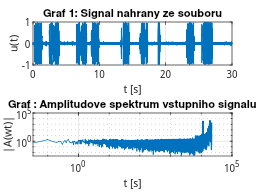

amplitude_spectrum_graph = amplitude_spectrum(fft_freq > 0);
fft_freq_graph = fft_freq(fft_freq>0);

subplot(2,1,2);   % 2 v druhe casti pole FIG1
semilogx(fft_freq_graph,amplitude_spectrum_graph);
yscale log;

%Uprava stylu grafu
grid on;                                                % Zapnuti gridu
title("Graf : Amplitudove spektrum vstupniho signalu")  % Nadpis
xlabel("t [s]");                                        % Popis osy X
ylabel("|A(wt)|");    

Pro odfiltrovani signalu vytvorime 2 masky. 1. Maska na zaklade vyselektovane oblasti (2 okna), a druha maska obsahujici amplitudy vyssi, nez je nastaveny amplitude treshodl. Tyto masky pote sloucime a vymaskujeme jim vysledny signal.

window_mask = zeros(signal_size, 1);
window_mask(fft_freq>(-abs_omega_max))=1;
window_mask(fft_freq>(-abs_omega_min))=0;
window_mask(fft_freq>(abs_omega_min))=1;
window_mask(fft_freq>(abs_omega_max))=0;

amplitude_mask = zeros(signal_size, 1);
amplitude_mask(amplitude_spectrum > amp_filter_treshold) = 1;

master_mask = ~(window_mask.*amplitude_mask); 

fft_sig_filtered = master_mask.*fft_sig;

Pote muzeme vyfiltrovany audiozaznam ulozit do noveho souboru 

destination_folder = "/home/neo/Documents/Projekty/BPC-SAS_final/peroutik_vut/BPC-SAS";
audiowrite(destination_folder+"256371_filtered_ukol1.wav",ifft(fft_sig_filtered),sample_rate);